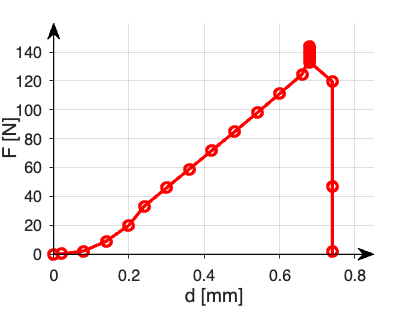

% Clear workspace and figures
clear;
close all;
clc;

% === Load Data from CSV ===
%filename = "sample6-3tests/arduino_data32.csv"; % Ensure this file exists in your working directory
%filename = 'TPU-16.05.25/arduino_dataPERIODIC.csv';
filename = "sample3/arduino_data15.csv";
rawData = readmatrix(filename);

% === Define Conversion Constants ===
distanceConversionFactor = 0.02; % Convert encoder ticks to mm or other units
forceConversionFactor = 0.0000478305936073059;    % Convert raw load cell reading to Newtons

% === Extract and Convert Columns ===
% Assuming CSV is structured as [EncoderValue, LoadCellValue]
EncoderDistance = rawData(:, 1) * distanceConversionFactor;
LoadCellReading = rawData(:, 2) * forceConversionFactor;

% === Plot Force vs Distance ===
figure;
plot(EncoderDistance, LoadCellReading, '-o', 'LineWidth', 2, 'Color', 'r');

xlim([0 0.85]);  % Only show x >= 0
ylim([0 160]);  % Only show y >= 0
yticks(0:20:140);

% Shift plot area up
ax = gca;
pos = ax.Position;
pos(2) = pos(2) + 0.07;
pos(4) = pos(4) - 0.07;
set(ax, 'Position', pos);

grid on;

% Move x-label down
xl = xlabel('d [mm]', 'FontSize', 12);
set(xl, 'Units', 'normalized');
xlPos = get(xl, 'Position');
xlPos(2) = xlPos(2) - 0.08;
set(xl, 'Position', xlPos);

% Move y-label left
yl = ylabel('F [N]', 'FontSize', 12);
set(yl, 'Units', 'normalized');
ylPos = get(yl, 'Position');
ylPos(1) = ylPos(1) - 0.05;
set(yl, 'Position', ylPos);

% Add axis arrows
annotation('arrow', [pos(1), pos(1) + pos(3)], [pos(2), pos(2)]);
annotation('arrow', [pos(1), pos(1)], [pos(2), pos(2) + pos(4)]);

set(gca, 'TickDir', 'out');      % or 'none' to remove completely
set(gca, 'Box', 'off');          % removes top and right axes

exportgraphics(gcf, 'figures/Rupture.png', 'Resolution', 600);  % High quality